# Repaso Semana 1 & 2

#### Métodos Númericos

#### *Resumen sobre la semana 1 y 2*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- No olvidar el criterio de parada de ErrorRelativo, ya que en general este error converge primero que el Error Absoluto, y esto detiene el metodo antes de un delta deseado, si el método se encuentra programado de esta manera es importante no modificar este criterio, y de igual manera esto se verá reflejado en el criterio $\textrm{Err}$ que nos retorna el método.

- Importante, pero esto es más un recordatorio. Matlab es además de un software un lenguaje, así podemos tareas repetitivas volverlas métodos iterativos, eso es lo que se les propone con el método **Jac_GS**, invitarlos a que exploren la posibilidad y realicen métodos que les haga la vida más fácil.

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Métodos de una variable*

`    [c, err, n] = bisect(Function, Num1, Num2, Tol), `Método de bisección.

            - Function funcion definida @

            - Num1 y Num2 son los extremos del intervalo

            - Tol Es la tolerancia definida a la iteración

            - c es la aproximación obtenida por el método

            - err Error asociado a la iteración

            - n Pasos realizados para alcanzar la tolerancia

`    [p, k, err, P] = fixpt(g, p0, tol, max1), `Método de punto fijo.

            - g funcion creada con @

            - p0 es el supuesto inicial para el punto fijo

            - tol es la tolerancia

            - max1 es el numero maximo de iteraciones

            - p es la aproximacion del punto fijo

            - k es el numero de iteraciones realizadas

            - err es el error en la aproximacion

            - P' contiene la secuencia {pn}

`    [p, err, k, yc] = newton(f, df, p0, delta, epsilon, max1), `Método de Newton.

            - f funcion creada con @

            - df funcion derivada creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

`    [p, err, k, yc] = newton(f, df, d2f, p0, delta, epsilon, max1), `Método de Newton modificado.

            - f funcion creada con @

            - df primera derivada, funcion creada con @

            - d2f segunda derivada, funcion creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

*Frente a la definición del método de Newton acelerado, recordemos que este puede ser invocado usando el método de Newton y agrendando la multiplicidad de la raiz a hallar en la definición de la función o en la definición de la derivada de la función, tal como se indica:*

$x_{k+1} =x_k -M\frac{\;f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$ : Definimos entonces $f\left(x_k \right):=M\;f\left(x\right)\;|\;f^{\prime } \left(x_k \right):=\frac{f^{\prime } \left(x\right)}{M}$.

#### *        Métodos de sistemas de ecuaciones*

`    X = jacobi(A, B, P, delta, max1), `Método de Jacobi.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; los supuestos iniciales

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de jacobi a

                la solucion de  AX = B

`    X = gseid(A, B, P, delta, max1), `Método de Gauss - Seidel.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de gauss-seidel a

                la solucion de  AX = B

`    Y = sor(A, B, P, w, delta, max1), `Método de SOR

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - w parametro de sobrerelajacion (0 < w < 2)

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

             - Y es una matriz  N x 1: la aproximacion de SOR a

                la solucion de  AX = B

`    P = newdim (F, JF, P, delta, epsilon, max1), `Método de Newton

            - F funcion del sistema creada con @

            - JF matriz jacobiana, funcion creada con @

            - P es la aproximacion inicial a la solucion

            - delta es la tolerancia para  P

            - epsilon es la tolerancia para  F(P)

            - max1 es el numero maximo de iteraciones

            - P es la aproximacion a la solucion

            - iter es el numero de iteraciones realizadas

            - err es el error estimado para  P

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

*Enfrentemos un problema típico ejemplo para cada una de las rutinas, por lo que definimos:*

### Bisección

Para los siguientes problemas de la forma $f\left(x\right)=0$, aproxime una raíz por medio del método de Newton o Bisección

$2^{-x} +e^x +2\;\cos \left(x\right)-6=0$, en $\left\lbrack 1,3\right\rbrack$

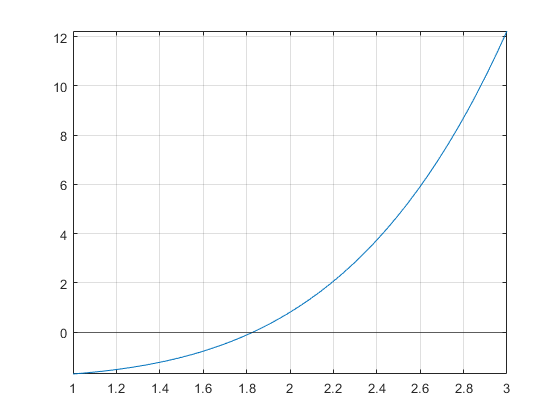

clear % Limpiamos las variables
syms f(x) % Definimos las variables del problema

f(x) = 2^(-x) + exp(x) + 2*cos(x) - 6; % Definimos la función

clf('reset') % Limpiamos la figura
fplot(f, [1, 3]) % Gráficamos la función
yline(0) % Dibujamos una linea en y = 0, para ver las raices
grid on % Activamos la gradilla de la figura

f = matlabFunction(f); % Procesamos la función
[c, err, yc] = bisect(f, 1, 3, 1e-15) % Aplicamos el método

c = 1.8294

err = 1.7764e-15

yc = 50

### Punto fijo

Aproxime el punto fijo de la función $g\left(x\right)=\cos \left(x\right)$ en el intervalo $\left\lbrack 0,1\right\rbrack$. Utilice $p_0 =1$ como primera aproximación

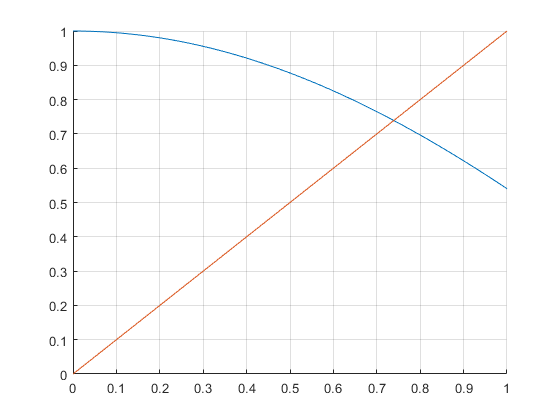

clear % Limpiamos las variables
syms g(x) % Definimos las variables

g(x) = cos(x); % Definimos la función

clf('reset') % Limpiamos la figura
hold on % Mantenemos el mismo gráfico para las funciones
fplot(g, [0, 1]) % Gráficamos la función
fplot(x, [0, 1]) % Gráficamos la función
grid on % Activamos la gradilla
hold off % Soltamos el gráfico

g = matlabFunction(g); % Procesamos la función
[p, k, err] = fixpt(g, 1, 1e-15, 100) % Aplicamos el método

p = 0.7391

k = 88

err = 7.7716e-16

### Newton

Se usa el método de Newton para aproximar la raiz 0 de


$$x\;e^x -e^x +1=0$$
 

¿Cuál es el orden de convergencia del método de Newton para este ejemplo? Justifique su respuesta

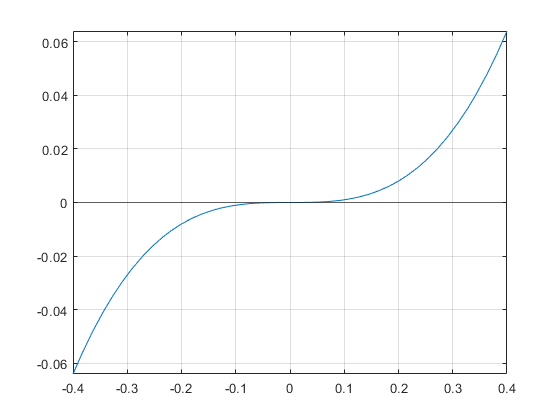

clear % Limpiamos variables
syms f(x) % Definimos las variables

f(x) = x*exp(x) - exp(x) + 1; % Definimos la función
df(x) = diff(f, x); % Derivamos la función
d2f(x) = diff(df, x); % Segunda derivada de la función
d3f(x) = diff(d2f, x); % Tercera derivada de la función

clf('reset') % Limpiamos la función
fplot(x^3, [-.4, .4]) % Gráficamos la función
yline(0) % Generamos una linea en y = 0
grid on % Activamos la gradilla

Cero de multiplicidad par.

f(0), df(0), d2f(0), d3f(0) % Multiplicidad de la raiz es 2

$$ans = 0$$

$$ans = 0$$

$$ans = 1$$

$$ans = 2$$

f = matlabFunction(f); % Procesamos la función f
df = matlabFunction(df); % Procesamos la función df
d2f = matlabFunction(d2f); % Procesamos la función d2f

Newton:

[p0, err, k, y] = newton(f, df, 1/2, 1e-5, 1e-15, 20) % Aplicamos los métodos

p0 = 5.2880e-06

err = 5.2879e-06

k = 17

y = 1.3981e-11

Newton Acelerado: $x_{k+1} =x_k -M\frac{f\left(x_k \right)\;}{f^{\prime } \left(x_k \right)}$

Mdf = @(x) df(x) / 2; % Definimos la derivada con la multiplicidad
[p0, err, k, y] = newton(f, Mdf, 1/2, 1e-5, 1e-15, 20)

p0 = -9.7481e-12

err = 1.0630e-06

k = 4

y = 0

Newton Modificado:

[p0, err, k, y] = newtonMod(f, df, d2f, 1/2, 1e-5, 1e-15, 20)

p0 = 7.2132e-11

err = 2.4093e-06

k = 4

y = 1.1102e-16

### Jacobi

En cada caso, utilice los métodos de Jacobi y Gauss-Seidel para aproximar las soluciones de los sistemas lineales Ax = b. En todos los casos use el vector nulo como primera aproximación.

  
$$A=\left\lbrack \begin{array}{cccc}
4 & 1 & -1 & 1\\
1 & 4 & -1 & -1\\
-1 & -1 & 5 & 1\\
1 & -1 & 1 & 3
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
-2\\
-1\\
0\\
1
\end{array}\right\rbrack$$


clear

A = [4 1 -1, 1; 1 4 -1 -1; -1 -1 5 1; 1 -1 1 3]; % Definimos la matriz del sistema de ecuaciones
b = [-2 -1 0 1]'; % Definimos el vector resultado
x0 = zeros(size(b)); % Definimos la iteración inicial

Xjacobi = jacobi(A, b, x0, 1e-15, 100) % Aplicamos directamente el método

### Gauss-Seidel

En cada caso, utilice los métodos de Jacobi y Gauss-Seidel para aproximar las soluciones de los sistemas lineales Ax = b. En todos los casos use el vector nulo como primera aproximación.

  
$$A=\left\lbrack \begin{array}{cccc}
4 & 1 & -1 & 1\\
1 & 4 & -1 & -1\\
-1 & -1 & 5 & 1\\
1 & -1 & 1 & 3
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
-2\\
-1\\
0\\
1
\end{array}\right\rbrack$$


clear

k = 68

err = 1.0296e-15

relerr = 9.6994e-16

Xjacobi =    -0.7534
    0.0411
   -0.2808
    0.6918



A = [4 1 -1, 1; 1 4 -1 -1; -1 -1 5 1; 1 -1 1 3]; % Definimos la matriz del sistema de ecuaciones
b = [-2 -1 0 1]'; % Definimos el vector resultado
x0 = zeros(size(b)); % Definimos la iteración inicial

Xgseid = gseid(A, b, x0, 1e-15, 100) % Aplicamos directamente el método

### SOR

En cada caso, utilice los métodos de Jacobi y Gauss-Seidel para aproximar las soluciones de los sistemas lineales Ax = b. En todos los casos use el vector nulo como primera aproximación.

  
$$A=\left\lbrack \begin{array}{ccc}
1 & 0 & -1\\
-\frac{1}{2} & 1 & -\frac{1}{4}\\
1 & -\frac{1}{2} & 1
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
\frac{1}{5}\\
-1\ldotp 425\\
2
\end{array}\right\rbrack$$


Use en lugar de $-1$ utilice $-2$ en la componente $\left(1,3\right)$ de $A$. ¿Siguen siendo convergentes los dos métodos?

clear

A = [1 0 -1; -1/2 1 -1/2; 1 -1/2 1]; % Definimos la matriz A
b = [1/5 -1.425 2]'; % Definimos el vector solución
x0 = zeros(size(b)); % Definimos la aproximación inicial

k = 35

err = 4.3710e-16

relerr = 4.1178e-16

Xgseid =    -0.7534
    0.0411
   -0.2808
    0.6918



A(1, 3) = -2; % Realicemos el cambio pedido.
Jac_GS(A); % Verifiquemos los radios espectrales de las matrices iterativas

Veamos que tras los métodos diverger, podemos considerar el uso del método de SOR, donde podemos considerar el uso de sobre/sub relajación:

Jac_GS(A, 1/2); % Verifiquemos el radio de SOR sub relajado
Jac_GS(A, 3/2); % Verifiquemos el radio de SOR sobre relajado

Para el método de SOR subrelajado, veamos que existe convergencia.

Y = sor(A, b, x0, 1/2, 1e-15, 100)

### Newton Multivariado

Utilice el método de Newton para aproximar la raiz del sistema


$$\begin{array}{l}
x^3 +3y^2 =21\\
x^2 +2y+2=0
\end{array}$$


Como primera aproximación considerar $x_0 =\;\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$

clear
clf('reset')
syms F(x, y)

F =  [x^3 + 3*y^2 - 21, x^2 + 2*y + 2]'; % Definimos la función

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.3509

ratioTGS = 1.2500

ratioTw = 1.2500


% Para ejemplo ilustrativo, conozcamos el sistema de ecuaciones:

Radio Espectral


ratioTJ = 1.3509

ratioTGS = 1.2500

ratioTw = 0.5809

F1 = @(x, y) x.^3 + 3.*y.^2 - 21; % Componente 1 de F

Radio Espectral


ratioTJ = 1.3509

ratioTGS = 1.2500

ratioTw = 2.7924

F2 = @(x, y) x.^2 + 2.*y + 2; % Componente 2 de F


k = 62

err = 9.9301e-16

relerr = 6.9466e-16

Y =     1.2111
   -0.5667
    0.5056


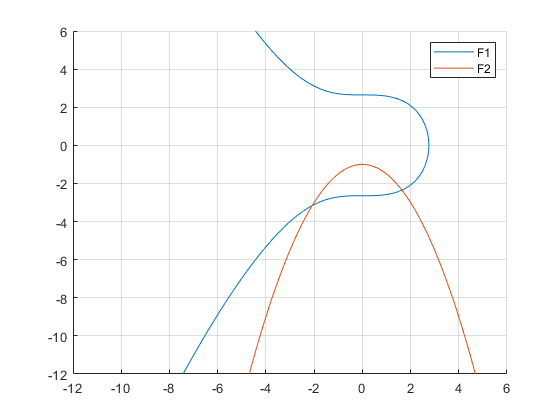

$$JF(x, y) = \left(\begin{array}{cc} 3\,x^{2} & 6\,y\\ 2\,x & 2 \end{array}\right)$$

err = 4.4108e-10

relerr = 1.5383e-10

iter = 19

P =     1.6430
   -2.3498


err = 1.2609e-07

relerr = 3.3321e-08

iter = 5

Q =    -2.0793
   -3.1617


clf('reset')
hold on
fimplicit(F1,[-12 6]);
fimplicit(F2,[-12 6]);
legend('F1', 'F2')
grid on
hold off
x0 = ones(size(F));
JF(x, y) = jacobian(F, [x, y])
F = matlabFunction(F); % Procesamos la función
JF = matlabFunction(JF); % Procesamos el Jacobiano
F = @(x) F(x(1), x(2)); % Dejamos la función de argumento vectorial
JF = @(x) JF(x(1), x(2)); % Dejamos el Jacobiano de argumento vectorial

P = newdim(F, JF, x0, 1e-5, 1e-15, 100) % Esta es la solución positiva
Q = newdim(F, JF, -2*x0, 1e-5, 1e-15, 100) % Esta es la solución negativa